# First Order Two Dimensional Linear Systems

In this section, we try to solve $\mathbf{A}_1\mathbf{u}_x+\mathbf{A}_2\mathbf{u}_y+\mathbf{A}_0\mathbf{u}=\mathbf{f}(x,y)$ for $x,y\in\Omega$, $\Omega$ polygonal w.r.t Dirichlet boundary conditions $\mathbf{u}(x,y)=\mathbf{g}(x,y)$ for $x\in\partial\Omega$ where $\mathbf{A}_i\in\mathbb{R}^{m\times m}$ and $\mathbf{u},\mathbf{f},\mathbf{g}\in\mathbb{R}^{m\times 1}$. For ellpticity, we require $\mathrm{det}(\alpha_1\mathbf{A}_1+\alpha_2\mathbf{A}_2)\neq0$ for $\forall \alpha_1,\alpha_2\neq 0$. 

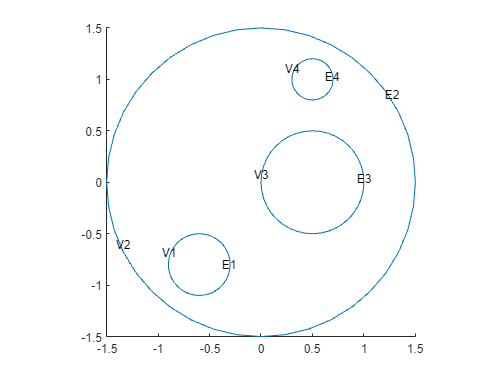

% Construct the model
m  = 3 ;  % number of dependent variables

t = pi/20 : pi/20 : 2*pi;
Omega = polyshape({1.5*cos(t), 0.5+0.5*cos(t), 0.5+0.2*cos(t), -0.6+0.3*cos(t)}, ...
                  {1.5*sin(t), 0.5*sin(t), 1+0.2*sin(t), -0.8+0.3*sin(t)});  % Omega
model = Collocation2D(m, Omega); % Construct the model
model.gm.pdegplot(VertexLabels="on",EdgeLabels="on");

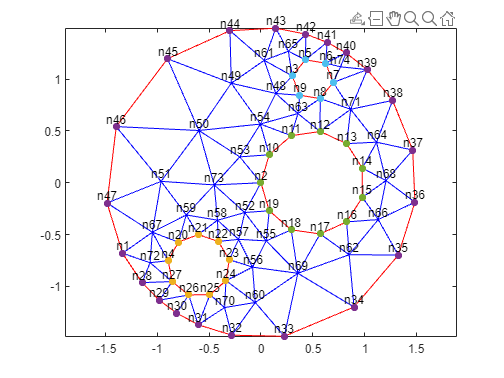

74 Nodes (222 unknowns) and 105 Elements generated


beta = 5 ; hmax=0.15 ;                    % mesh size, hmin=hmax/beta 
model.discretize(hmax, beta, 'linear');  % Discretization

if true 
    model.gm.pdemesh(); %(ElementLabels="on", NodeLabels="on") ;
    hold on
    edge = model.boundary_decompose();
    for i = 1:model.gm.NumEdges
        scatter(edge{i}(1:end-1,1), edge{i}(1:end-1,2), "filled")
    end
    hold off
    fprintf('%d Nodes (%d unknowns) and %d Elements generated', size(model.gm.Mesh.Nodes,2), ...
            size(model.gm.Mesh.Nodes,2)*m, size(model.gm.Mesh.Elements,2));
end

The above `gm.Mesh.Nodes` stores the $(x,y)$ coordinates for each global vertex. `gm.Mesh.Elements `provides the local-to-global map and local vertices are stored in a counterclockwise order.

% Sample Equation
% Sloution Benchmark: poisson
u    = @(x,y) [sin(x.^2 + y.^2);  2*x.*cos(x.^2 + y.^2); 2*y.*cos(x.^2 + y.^2)]; % u=[phi, v1, v2]

% System Settings
num_eq = 4;
A1 = @(x,y) [1,0,0; 0,0,0; 0,-1,0; 0,0,1];
A2 = @(x,y) [0,0,0; 1,0,0; 0,0,-1; 0,-1,0];
A0 = @(x,y) [0,-1,0; 0,0,-1; 0,0,0; 0,0,0];
ff = @(x,y) 4*cos(x.^2 + y.^2) - 4*(x.^2 + y.^2).*sin(x.^2 + y.^2);
f  = @(x,y) [0 ; 0; -ff(x,y); 0];

num_cond = 2;
B1 = [];
B2 = [];
B0 = @(x,y) [1,0,0; 0, model.boundary_normal([x,y], 2), -model.boundary_normal([x,y], 1)];
g1 = @(x,y) sin(x.^2 + y.^2);
g2 = @(x,y) model.boundary_normal([x,y]) * [-2*y.*cos(x.^2 + y.^2); 2*x.*cos(x.^2 + y.^2)];
g  = @(x,y) [g1(x,y); g2(x,y)];

% Construct the model
model.fitInterior(A1, A2, A0, f, num_eq);
model.fitBoundary(B1, B2, B0, g, num_cond);
model.fitTrueSol(u);

The following functions help to sample points from the boundary and the within the domain.

% Coordinates of the closed boundary nodes
rng(42) ;  % random seed
N_loc = 100; % N_loc points per element 14
sampled_boundary_nodes = model.gm.Mesh.Nodes(:,model.BoundaryNodeIDs)' 

sampled_boundary_nodes =    -1.3365   -0.6810
         0    0.0000
    0.3025    1.0313
   -0.8963   -0.7531
    0.3508    1.1330
    0.4464    1.1925
    0.5591    1.1910
    0.6530    1.1288
    0.6982    1.0256
    0.6806    0.9144


sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc);

N_Omega = size(sampled_interior_nodes, 1); N_Gamma = size(sampled_boundary_nodes, 1);
fprintf('N_Omega: %d, N_Gamma: %d, total: %d', N_Omega, N_Gamma, N_Omega + N_Gamma);

N_Omega: 63000, N_Gamma: 108, total: 63108

fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);

eq_Omega: 252000, eq_Gamma: 216, eq_total: 252216

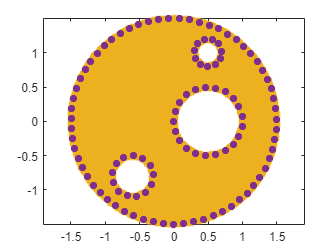


% Plot mesh and sampled points
if true 
    model.gm.pdemesh();
    hold on
    scatter(sampled_interior_nodes(:,1), sampled_interior_nodes(:,2))
    scatter(sampled_boundary_nodes(:,1), sampled_boundary_nodes(:,2), "filled")
    hold off
end

% System assemble
Lambda = diag(200*ones(1,num_cond));     % square(weights) for BC
[B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(sampled_interior_nodes);
[B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
B = [B_Omega ; B_Gamma];  d = [d_Omega ; d_Gamma];

fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);

eq_Omega: 252000, eq_Gamma: 216, eq_total: 252216

fprintf('num_eq: %d, num_unknown: %d, ratio m/n: %.2f', size(B,1), size(B,2), size(B,1)/size(B,2));

num_eq: 252216, num_unknown: 1101, ratio m/n: 229.08

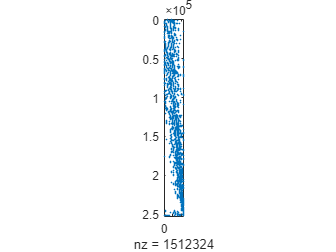

spy(B); c = B\d; model.C = model.reshape2mat(c);

% save('./data/2DsktSample/2DsktSampleModel_small.mat', 'model');

% Solution evaluation
grid_size = [100, 100]; % [x_size, y_size]
[X, Y, in, XY] = model.OmegaMeshgrid(grid_size);
u_fit = model.evaluate_LSFEM(XY);

u_fit =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


u_true = model.u(XY(:,1)', XY(:,2)');

u_true =    -0.9753   -0.9516   -0.9209   -0.8839   -0.8414   -0.7940   -0.7424   -0.6874   -0.6295   -0.5693   -0.5076   -0.4447   -0.3813   -0.3177   -0.2545   -0.1919   -0.1304   -0.0701   -0.0115    0.0454    0.1003    0.1530    0.2036    0.2518    0.2977    0.3412    0.3823    0.4210    0.4573    0.4912    0.5229    0.5524    0.5796    0.6048    0.6280    0.6492    0.6686    0.6862    0.7022    0.7164    0.7292    0.7405    0.7503    0.7589    0.7661    0.7720    0.7767    0.7803    0.7827    0.7839
    0.6612    0.9204    1.1671    1.4000    1.6178    1.8199    2.0054    2.1742    2.3261    2.4610    2.5793    2.6813    2.7674    2.8385    2.8950    2.9379    2.9680    2.9862    2.9934    2.9905    2.9785    2.9583    2.9309    2.8971    2.8578    2.8139    2.7662    2.7154    2.6622    2.6075    2.5517    2.4955    2.4394    2.3839    2.3296    2.2769    2.2260    2.1775    2.1315    2.0884    2.0485    2.0119    1.9789    1.9496    1.9242    1.9027    1.8854    1.8722    1.8633

u_fit  = model.reshapeRowsTo3D(u_fit, grid_size(2), grid_size(1));
u_true = model.reshapeRowsTo3D(u_true, grid_size(2), grid_size(1)) .* in;

X_label = round(X(1,:),2);
Y_label = round(Y(:,1),2);

% model.indomain([0.5,0]) * model.u(0.5,0)
% model.evaluate_LSFEM_elewise([0.5,0])

% Plot output
fprintf('u_1');

u_1

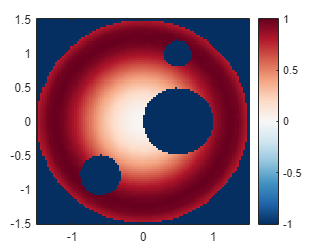

@author : slandarer


imagesc(X_label, Y_label, u_fit(:,:,1));
colorbar;
clim([-1 1]);
set(gca,'YDir','normal');
colormap(flipud(slanCM(97)));

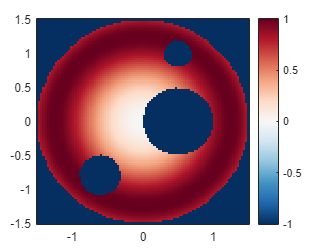


imagesc(X_label, Y_label, u_true(:,:,1));
colorbar;
clim([-1 1]) ;
set(gca,'YDir','normal');

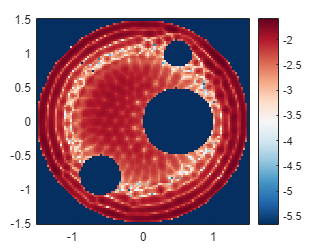


error1 = log10(abs(u_fit(:,:,1) - u_true(:,:,1))); % )./abs(u_true(:,:,1)) ;
imagesc(X_label, Y_label, error1);
colorbar;
%clim([0 0.1]) ;
set(gca,'YDir','normal');


fprintf('u_2');

u_2

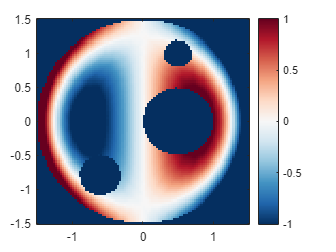

imagesc(X_label, Y_label, u_fit(:,:,2));
colorbar ;
clim([-1 1]);
set(gca,'YDir','normal');

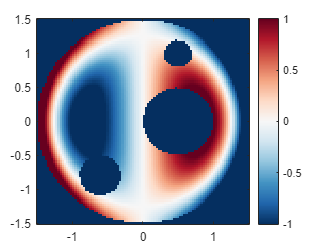


imagesc(X_label, Y_label, u_true(:,:,2));
colorbar;
clim([-1 1]);
set(gca,'YDir','normal');

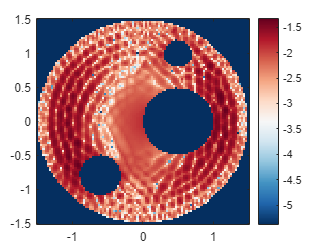


error2 = log10(abs(u_fit(:,:,2) - u_true(:,:,2))); %)./abs(u_true(:,:,2)) ;
imagesc(X_label, Y_label, error2);
colorbar;
%clim([0 0.1]) ;
set(gca,'YDir','normal');


fprintf('u_3');

u_3

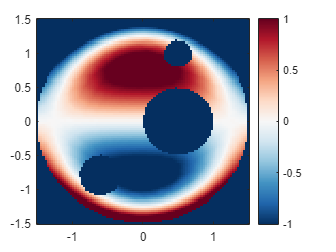

imagesc(X_label, Y_label, u_fit(:,:,3));
colorbar ;
clim([-1 1]);
set(gca,'YDir','normal');

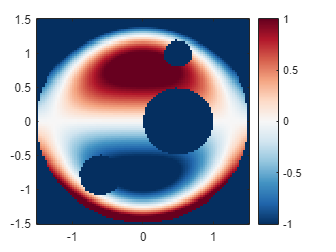


imagesc(X_label, Y_label, u_true(:,:,3));
colorbar;
clim([-1 1]);
set(gca,'YDir','normal');

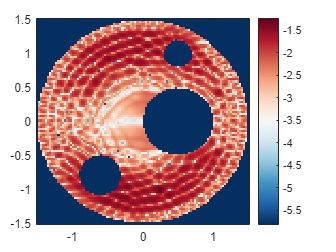


error3 = log10(abs(u_fit(:,:,3) - u_true(:,:,3))); %)./abs(u_true(:,:,2)) ;
imagesc(X_label, Y_label, error3);
colorbar;
%clim([0 0.1]) ;
set(gca,'YDir','normal');

% Plot Basis
figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(3,6); 
colormap(flipud(slanCM(97)));

@author : slandarer


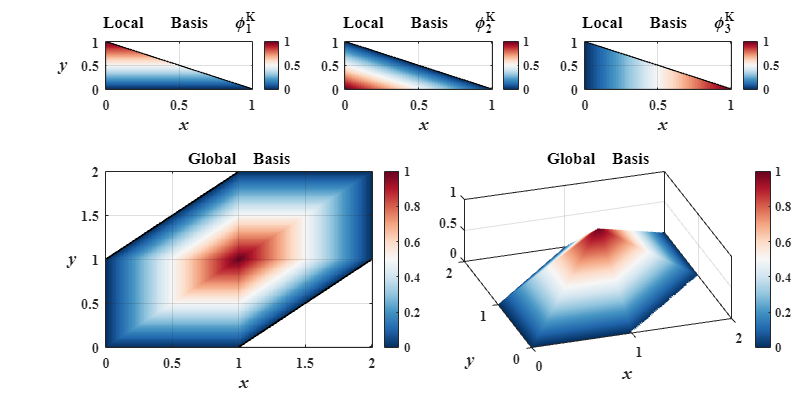

[x,y] = meshgrid(0:0.01:1);
% Local basis
nexttile(1,[1,2]);
phi1 = y; phi1( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi1);
set(h, 'AlphaData', ~isnan(phi1)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_1'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y ",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360); 
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(3,[1,2]);
phi2 = 1-x-y; phi2( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi2);
set(h, 'AlphaData', ~isnan(phi2)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_2'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(5,[1,2]);
phi3 = x; phi3( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi3);
set(h, 'AlphaData', ~isnan(phi3)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_3'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold'); 
c = colorbar; set(c,'TickLabelInterpreter','tex');

% Global basis
ele1val = @(x,y) (x - y + 1).*( y <= x+1 ).*( x <= 1 ).*( y >= 1 );
ele2val = @(x,y) (2 - y).*( x>1 ).*( y>=x ).*( y<=2 );
ele3val = @(x,y) (2 - x).*( x<=2 ).*( y<x ).*( y>=1 );
ele4val = @(x,y) (- x + y + 1).*( y<1 ).*( y>=x-1 ).*( x>=1 );
ele5val = @(x,y) (y).*( x<1 ).*( y<=x ).*( y>=0 );
ele6val = @(x,y) (x).*( x>=0 ).*( y>x ).*( y<1 );
[x,y] = meshgrid(0:0.01:2);
phi = ele1val(x,y) + ele2val(x,y) + ele3val(x,y) + ele4val(x,y) + ele5val(x,y) + ele6val(x,y);
phi( y > x+1 ) = nan; phi( y < x-1 ) = nan;

nexttile(10,[2,3]);
surfc(x, y, phi, 'LineStyle', 'none'); alpha 1;
view([-18.60 55.80]); hold on; grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Global    Basis'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y ",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(7,[2,3]);
phi( y > x+1 ) = nan; phi( y < x-1 ) = nan;
h = imagesc(x(1,:), y(:,1), phi);
set(h, 'AlphaData', ~isnan(phi)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), x(1,:)-1, 'LineWidth', 1.5, 'Color', [0,0,0]);
plot(x(1,:), x(1,:)+1, 'LineWidth', 1.5, 'Color', [0,0,0]);
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Global    Basis'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);  
c = colorbar; set(c,'TickLabelInterpreter','tex');